# Perform Transmission Trade-Off Study for a Tractor

This example shows how to select a transmission pump and a motor based on a trade-off study for a tractor. This example also shows a trade-off study from the energy consumption by the tractor transmission components.

Copyright 2024 - 2025 The MathWorks, Inc.

To return to the repository main page, [click here](matlab:web('TractorModelOverview.html')).

## Transmission Trade-Off Study

A trade-off study is a systematic approach used to evaluate multiple options against each other to identify the best solution based on specific criteria. In the context of industrial tractor transmissions, conducting a trade-off study is crucial to balance performance, cost, and efficiency. The primary purpose of the trade-off study in this example is to determine the most energy-efficient choice among various transmission components. By analyzing different configurations, this study helps in selecting components that minimize energy consumption while maintaining required performance standards.

## Define Scenario, Operating Conditions and Drive Cycle

You can run a trade-off study for a given scenario and set of operating conditions. You can vary the road inclination angle to simulate the tractor plowing an uphill or downhill farm land. Define the road inclination angle in the Road Inclination Scenario subsystem under Scenario subsystem.

Select the implement type or specify the implement forces as functions of tractor velocity. This trade-off study uses a 5 cm straight point Chisel Plow as the implement with 5 number of tools and rake angle of ${55}^{\circ }$. Specify the implement depth in Implement Depth Command subsystem under Driver Controls subsystem. This study uses 8 cm as the implement depth. Define the engine speed in Engine Speed Command subsystem under Driver Controls subsystem. In this study the engine speed ramps up to a maximum of 2200 rpm in 7.3 seconds.

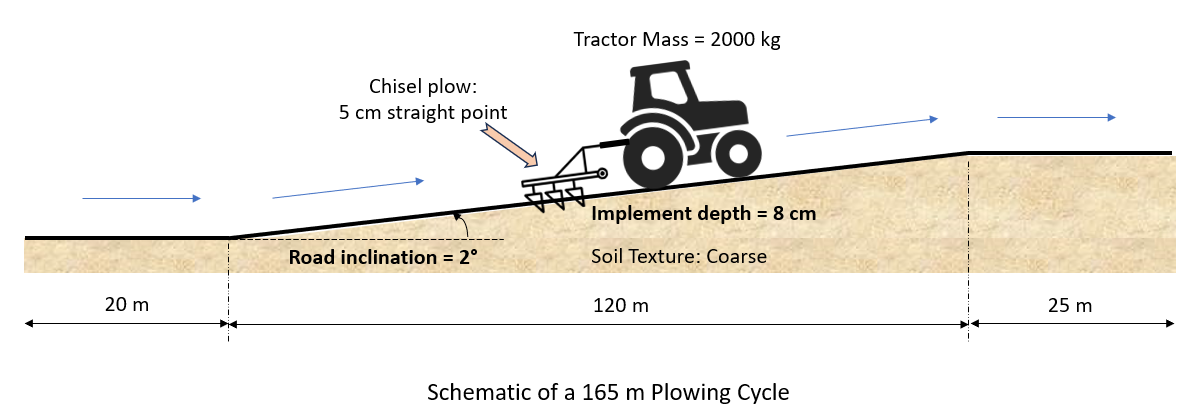

Define drive cycle as tractor target or desired velocity profile. This trade-off study shows the use of CVT control system to maintain the tractor velocity as per the desired velocity profile. Define desired velocity profile relative to the distance travelled.

distanceVector = [0,0.1389,0.4167,0.8333,1.3889,2.0833,2.9167,3.889,5,6.25,7.6389,200]; % Distance travelled in m
targetVelocityVector = [0,0.5,1,1.5,2,2.5,3,3.5,4,4.5,5,5]; % Target velocity in km/hr

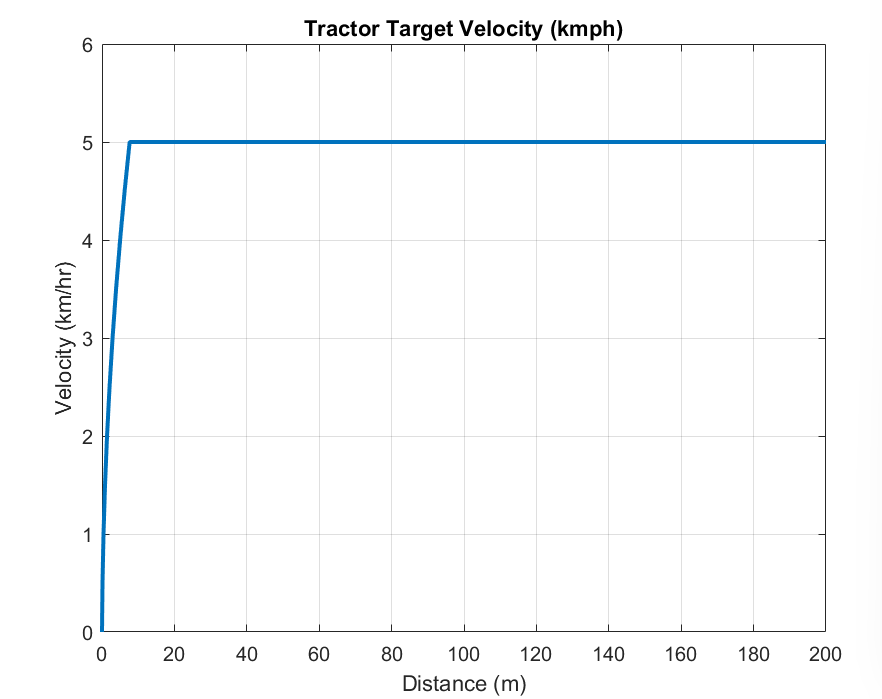

The desired velocity profile relative to simulation time is shown in this figure.

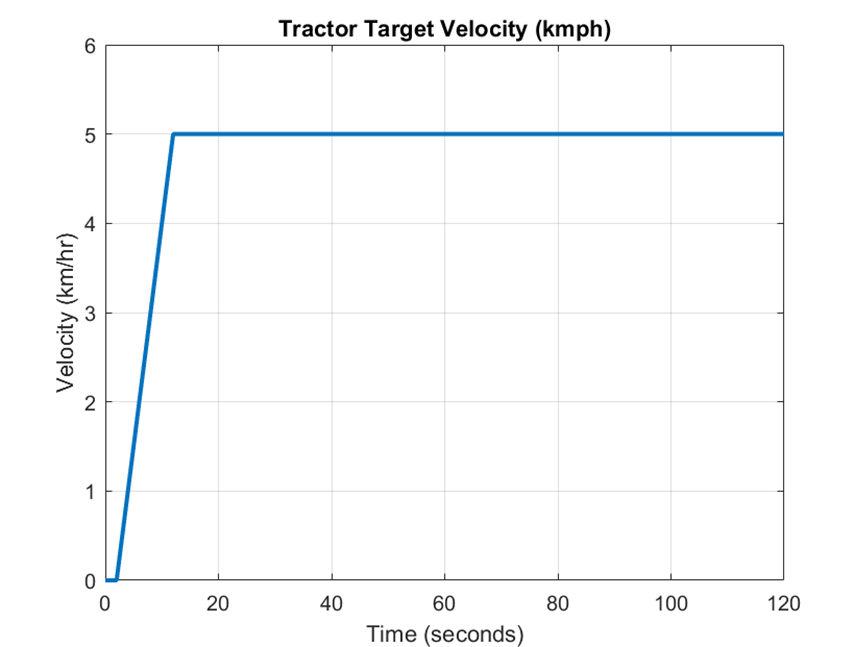

## Load Pump and Motor Dataset

Load the data for the pumps and the motors for the trade-off study. Determine the number of datasets for the pump and the motor.

load ('pumpData.mat');
load ('motorData.mat');
nPumpData = size(pumpData,2);
nMotorData = size(motorData,2);
numSims = nPumpData*nMotorData;

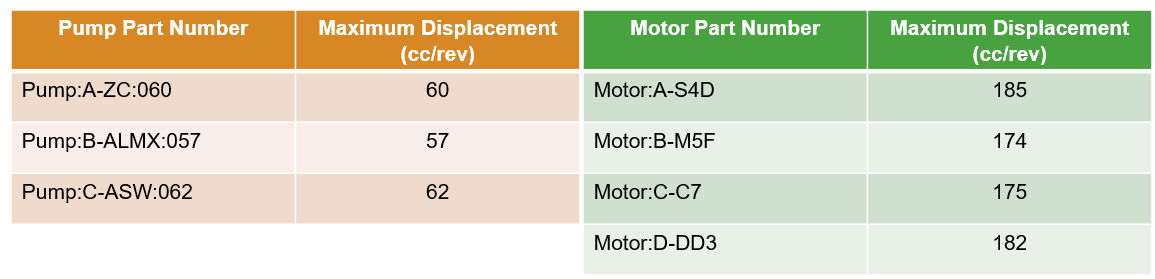

## Load Model and Define Simulation Input Object

Load the model. 

modelName = 'TractorTransmissionTradeOff';
load_system(modelName);
run('TractorEnergyComputationInput');

Define a Simulink.SimulationInput object.

simIn(1:numSims) = Simulink.SimulationInput(modelName);

Define the block paths for the transmission pump and the motor. 

pumpBlockPath = [modelName,'/Tractor/Tractor Body and Powertrain/Hydrostatic CVT/Main Pump/Pump'];
motorFrontBlockPath = [modelName,'/Tractor/Tractor Body and Powertrain/Hydrostatic CVT/Front Motor/Front Axle' ...
    newline 'Motor'];
motorRearBlockPath = [modelName,'/Tractor/Tractor Body and Powertrain/Hydrostatic CVT/Rear Motor/Rear Axle' ...
    newline 'Motor'];

## Set Parameters to Implement, Driver Controls, Transmission Pump and Motor

Set Draft (horizontal) force and vertical force computation to `Draft force prediction based on ASABE D497.5 standard` in the Implement subsystem mask. Specify the implement type, number of tools and rake angle. You can vary the pump displacement of the hydrostatic CVT to control the pump flow rate, that influences the tractor's velocity. The model uses a feedback PID controller in CVT Control System under Driver Controls subsystem to maintain the desired tractor velocity for each pump and motor combination.

simIn(1:numSims) = setBlockParameter(simIn(1:numSims),[modelName,'/Implement'],"methodForceComputation",...
    "Draft force prediction based on ASABE D497.5 standard");
simIn(1:numSims) = setBlockParameter(simIn(1:numSims),[modelName,'/Implement'],"typeImplement","Chisel Plow - 5 cm straight point");
simIn(1:numSims) = setBlockParameter(simIn(1:numSims),[modelName,'/Implement'],"numberTools","implement.numberTools");
simIn(1:numSims) = setBlockParameter(simIn(1:numSims),[modelName,'/Implement'],"angleRake","implement.angleRake");

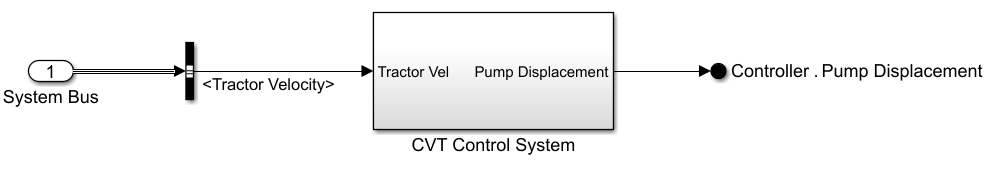

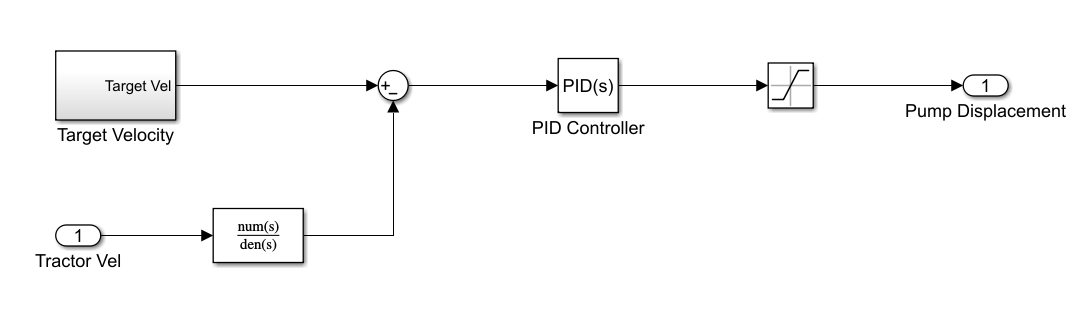

Define a `for` loop to include all possible combinations of pumps and motors. Repeat the operations for each pump and motor combination.

inputEnergyTotal = zeros(12,1);
lossFrontMotor = zeros(12,1);
lossRearMotor = zeros(12,1);
lossPump = zeros(12,1);
lossChargePump = zeros(12,1);
lossAux = zeros(12,1);
lossTransmissionTotal = zeros(12,1);
pumpHeatMap = cell(12,1);
motorHeatMap = cell(12,1);

for kk = 1:numSims
    remainder=mod(kk,nMotorData);
    quotient=floor(kk/nMotorData);
    if (remainder ~= 0)
        iPump = quotient+1;
        iMotor = remainder;
    else
        iPump = quotient;
        iMotor = nMotorData;
    end

Set the pump displacement saturation in the CVT Control System subsystem under Driver Controls subsystem.

    simIn(kk) = setBlockParameter(simIn(kk),[modelName,'/Driver Controls/CVT Control System/Saturation'],"UpperLimit",...
        num2str(pumpData(iPump).parameters.displacement_eff_TLU.value(2)));

Set the transmission pump and motor parameters by using the function `setParameterToBlock`.

    simIn(kk) = setParameterToBlock(simIn(kk), pumpBlockPath, pumpData(iPump));
    simIn(kk) = setParameterToBlock(simIn(kk), motorFrontBlockPath, motorData(iMotor));
    simIn(kk) = setParameterToBlock(simIn(kk), motorRearBlockPath, motorData(iMotor));
end

## Simulate Model for Each Dataset

Set stop time for simulation. Run the model.

SimT = 125;
simIn(1:numSims) = setModelParameter(simIn(1:numSims),"StopTime",string(SimT));

Select the method of computing from the drop down. This example uses serial computing. Use parsim for faster simulations using Parallel Computing Toolbox. Set the number of parallel workers for parsim.

fprintf ('%s','Simulating model for pump and motor datasets')

Simulating model for pump and motor datasets

methodComputeSim = "serial";
if (methodComputeSim == "serial")
    if exist('testScript', 'var') && testScript
    % This loop is used only for testing this |.mlx| file. The tests are located in 'Test' folder.
    simOut = sim(simIn,"ShowSimulationManager","off");
    else
    simOut = sim(simIn,"ShowSimulationManager","on");
    end
else
    numWorkers = 6; % Set number of parallel workers
    delete(gcp('nocreate'))
    parpool('local',numWorkers); % Running parallel simulations with local parpool
    if exist('testScript', 'var') && testScript
    % This loop is used only for testing this |.mlx| file. The tests are located in 'Test' folder.
    simOut = parsim(simIn,"ShowSimulationManager","off");
    else
    simOut = parsim(simIn,"ShowSimulationManager","on");
    end
end

[17-Feb-2025 11:12:56] Running simulations...
[17-Feb-2025 11:13:18] Completed 1 of 12 simulation runs
[17-Feb-2025 11:13:40] Completed 2 of 12 simulation runs
[17-Feb-2025 11:13:56] Completed 3 of 12 simulation runs
[17-Feb-2025 11:14:12] Completed 4 of 12 simulation runs
[17-Feb-2025 11:14:28] Completed 5 of 12 simulation runs
[17-Feb-2025 11:14:43] Completed 6 of 12 simulation runs
[17-Feb-2025 11:14:58] Completed 7 of 12 simulation runs
[17-Feb-2025 11:15:14] Completed 8 of 12 simulation runs
[17-Feb-2025 11:15:29] Completed 9 of 12 simulation runs
[17-Feb-2025 11:15:45] Completed 10 of 12 simulation runs
[17-Feb-2025 11:16:01] Completed 11 of 12 simulation runs
[17-Feb-2025 11:16:20] Completed 12 of 12 simulation runs


## Compute Energy Losses for Each Dataset

You can use the [`computeLosses`](matlab:open('../../Scripts/computeLosses.m')) function to calculate the energy loss using the simulation output data of front motor, rear motor, pump, charge pump, and auxiliary components, such as relief valves. You can also calculate the total input energy to the system or the total input energy from engine.

for kk = 1:numSims
    remainder=mod(kk,nMotorData);
    quotient=floor(kk/nMotorData);
    if (remainder ~= 0)
        iPump = quotient+1;
        iMotor = remainder;
    else
        iPump = quotient;
        iMotor = nMotorData;
    end

    [inputEnergyTotal(kk),lossFrontMotor(kk),lossRearMotor(kk),lossPump(kk),...
        lossChargePump(kk),lossAux(kk)] = computeLosses(simOut(kk).logsoutTractorTransmissionTradeOff);

    pumpHeatMap(kk) = cellstr(strcat("Pump:",string(pumpData(iPump).Manufacturer),"-",string(pumpData(iPump).PartNumber)));
    motorHeatMap(kk) = cellstr(strcat("Motor:",string(motorData(iMotor).Manufacturer),"-",string(motorData(iMotor).PartNumber)));
    lossTransmissionTotal(kk) = lossFrontMotor(kk)+lossRearMotor(kk)+lossPump(kk)+lossChargePump(kk)+lossAux(kk);
end

Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor
Calculating the energy losses for various components of tractor


## Display Trade-off Study Results

Create a heatmap that shows the total losses for the tractor transmission components for all the simulated datasets. This heatmap aggregates the transmission energy loss data and displays numbers and colors in each cell representing a dataset.

disp('Trade-off Study Results for Transmission Energy Loss in kJ')

Trade-off Study Results for Transmission Energy Loss in kJ


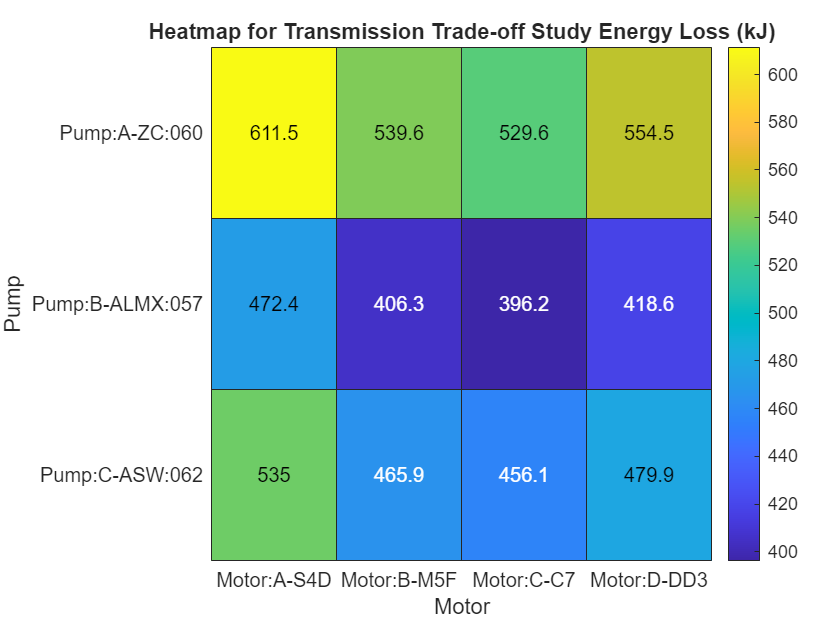

tbl = table(motorHeatMap,pumpHeatMap,lossTransmissionTotal,'VariableNames',{'Motor','Pump','Transmission Energy Loss (kJ)'});
h = heatmap(tbl,'Motor','Pump','ColorVariable','Transmission Energy Loss (kJ)','Colormap',parula);
h.Title = 'Heatmap for Transmission Trade-off Study Energy Loss (kJ)';

## Conclusion

The heatmap shows that for the combination of Pump B-ALMX:057 and Motor C-C7, the total transmission energy loss is the minimum among all datasets. This shows that the combination of Pump B-ALMX:057 and Motor C-C7 is the most energy efficient choice.